# FE Model Modes of a Cantilever - Frame elements

Consider the Cantilever shown below

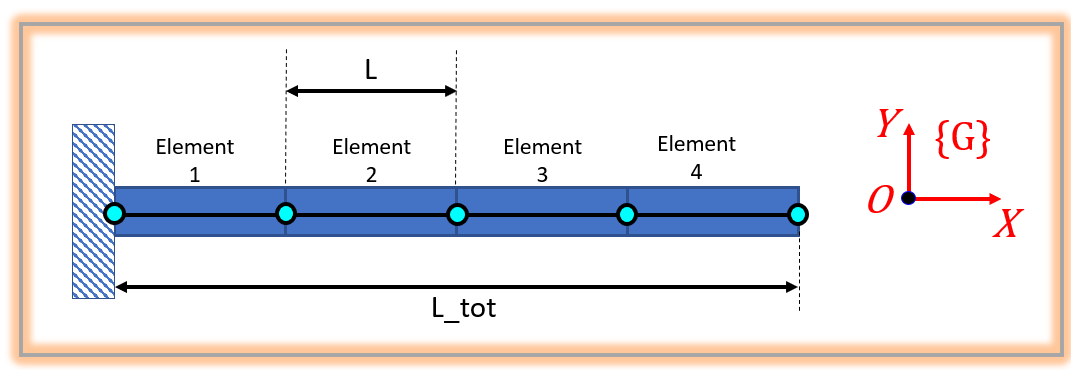

function FEM_tab = bh_cantil_FEM_modes(A, E, I, L_tot, density, opts_T)
arguments
    A        (1,1) double  {mustBeNumeric, mustBePositive}  % (m^2)
    E        (1,1) double  {mustBeNumeric, mustBePositive}  % (Pa)
    I        (1,1) double  {mustBeNumeric, mustBePositive}  % (m^4)
    L_tot    (1,1) double  {mustBeNumeric, mustBePositive}  % (m)
    density  (1,1) double  {mustBeNumeric, mustBePositive}  % (kg/m^3)
    opts_T.tf_do_plots (1,1) logical = false
    opts_T.NUM_ELES (1,1) double  {mustBeNumeric, mustBePositive, mustBeInteger} = 10
end

## Define the **LOCAL** element Stiffness and Mass matrices:

So specify the Number of nodes:

NUM_NODES =        opts_T.NUM_ELES + 1;
L         = L_tot/opts_T.NUM_ELES;

#   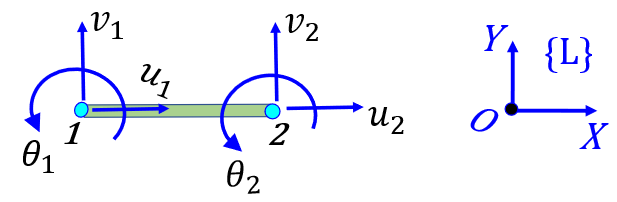 

The local stiffness matrix for the frame element can be defined as:   $[\thinspace ^LK_{ele} \thinspace] = F(A,E,I,L)$, where:

- A : is the cross sectional area  $\left(m^2 \right)$

- E : is Young's modulus $\left(N/m^2 \right)$

- I : is the 2nd moment of Area $\left(m^4 \right)$

- L : is the element's length $\left(m\right)$

See the SUBfunction `LOC_get_Kele_Mele_LOCAL()`

[K_ele, M_ele] = LOC_get_Kele_Mele_LOCAL(A, E, I, L, density);

Prepare the FULL system matrices

K_full   = zeros(3*NUM_NODES, 3*NUM_NODES);
M_full   = zeros(3*NUM_NODES, 3*NUM_NODES);

Here's how you could then apply this concept to the cantilever represented by many(many) elements:

% assemble the FULL system stiffness matrix
for ee=1:opts_T.NUM_ELES

    inds  = (1:6) + (ee-1)*3;
    K_full(inds, inds) = K_full(inds, inds) + K_ele;
    M_full(inds, inds) = M_full(inds, inds) + M_ele;   

end

## Apply the Boundary Conditions

% apply the boundary conditions
K_red = K_full(4:end, 4:end);
M_red = M_full(4:end, 4:end);

## Perform Modal Analysis

tmp_A        = inv(M_red) * K_red;
[eVec, eVal] = eig(tmp_A);
% whos eVec   eVal

**Sort the eigenvector columns based on the ascending order of the eigenvalues:**

[~,ind] = sort( diag(eVal) );

eVec    = eVec(:, ind);
eVal    = eVal(:, ind);

Since $M=M^T$  and  $K=K^T$ then let's normalize the Eigenvectors such that:  

-   
$$I\;\;={\;\;V}^T \ldotp M\ldotp V$$


tmp         = eVec.' * M_red * eVec;
tmp_row     =  diag(tmp)';
eVec_PHI    = eVec ./ sqrt( tmp_row );

Im_mat      = eVec_PHI.' * M_red * eVec_PHI;

Confirm the eigenvector normalization with a plot

if(true == opts_T.tf_do_plots)
    figure;
        heatmap(Im_mat, "Colormap", jet(20) );
            title("V^T . M . V")
end

And the above eigenvector scaling should also give us:

- 
$$\;\Omega^{2\;} =\;\;V^T \ldotp K\ldotp V$$


w2_mat      = eVec_PHI.' * K_red * eVec_PHI;

#### Great, so let's summarise what we have. 

Our UNdamped frequencies of vibration are:   $\omega \;\;\;\left\lbrack \frac{\mathrm{rad}}{\sec }\right\rbrack$:

w_list  = sqrt( diag(w2_mat) );
FEM_tab = array2table(                   [ w_list/(2*pi), w_list],...
                         'VariableNames',{'fn_Hz',       'wn_radpersec'});
end

# **Local Subfunctions ONLY beyond this point**

Define the Local Element Mass and Stiffness matrices

#   

The local stiffness matrix for the frame element can be defined as:   $[\thinspace ^LK_{ele} \thinspace] = F(A,E,I,L)$, where:

- A : is the cross sectional area  $\left(m^2 \right)$

- E : is Young's modulus $\left(N/m^2 \right)$

- I : is the 2nd moment of Area $\left(m^4 \right)$

- L : is the element's length $\left(m\right)$

Reference:

-    Rao, S., "Mechanical Vibrations, 2nd Edition", Addison Wesley, 1990

function [K_ele, M_ele] = LOC_get_Kele_Mele_LOCAL(A, E, I, L, density)

K_ele = ...
    [  %   u1             v1            th1           u2              v2            th2        
    ( A*E/L  ), (       0   ), (       0   ),   (-A*E/L  ), (       0   ), (       0   );
    (    0   ), ( 12*E*I/L^3), (  6*E*I/L^2),   (    0   ), (-12*E*I/L^3), (  6*E*I/L^2);
    (    0   ), (  6*E*I/L^2), (  4*E*I/L  ),   (    0   ), ( -6*E*I/L^2), (  2*E*I/L  );
    (-A*E/L  ), (       0   ), (       0   ),   ( A*E/L  ), (       0   ), (       0   );
    (    0   ), (-12*E*I/L^3), ( -6*E*I/L^2),   (    0   ), ( 12*E*I/L^3), ( -6*E*I/L^2);
    (    0   ), (  6*E*I/L^2), (  2*E*I/L  ),   (    0   ), ( -6*E*I/L^2), (  4*E*I/L  );
    ];

M_ele = (density*A*L/420) * ...
    [  %   u1           v1            th1          u2              v2            th2
      (140),          (0),           (0),        (70),            (0),           (0);
      (0),        (  156),        (22*L),         (0),           (54),       (-13*L);   
      (0),         (22*L),       (4*L^2),         (0),         (13*L),      (-3*L^2);
      (70),           (0),           (0),       (140),            (0),           (0);
      (0),           (54),        (13*L),         (0),          (156),       (-22*L); 
      (0),        (-13*L),      (-3*L^2),         (0),        (-22*L),       (4*L^2);
    ] ;  

end